# TA2: PID

## ANÁLISIS DE LA APROXIMACIÓN FOPDT FINAL

Basado en el modelo obtenido en el ensayo de PRBS y del escalón, se obtuvo:


$$\begin{array}{l}
G_{\textrm{FOPDT}} =\frac{K_p e^{-\textrm{Ls}} }{1+\textrm{Ts}}=\frac{\left(0\ldotp 98257\right)e^{-\left(0\ldotp 34639\right)s} }{1+\left(0\ldotp 50484\right)s}\\
T=0\ldotp 33053\\
L=0\ldotp 35938\\
K_{p\;} =0\ldotp 98448
\end{array}$$


% Defino el modelo FOPDT y los parámetros del PID
s = tf('s');

T =  0.33053;
L  = 0.35938;
K_p = 0.98448;

G_sin_retardo = (K_p)/(1+s*T);
G_fopdt = G_sin_retardo; 
G_fopdt.InputDelay = L; 
tf_fopdt_prbs_medida = G_fopdt;
tf_fopdt_ideal = G_fopdt

tf_fopdt_ideal =
 
                     0.9845
  exp(-0.359*s) * ------------
                  0.3305 s + 1
 
Continuous-time transfer function.



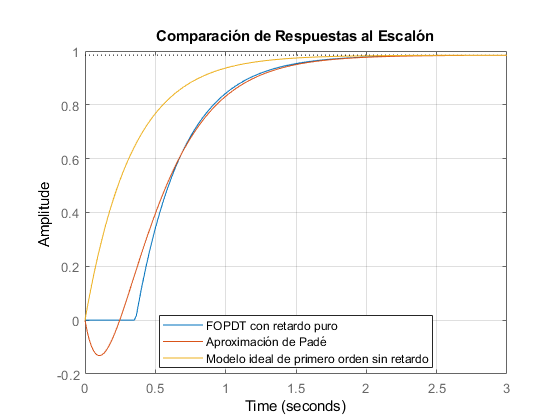

G_aprox = G_sin_retardo*(1-(s*L/2))/(1+(s*L/2));  %  Aproximado por Padé

% grafico

figure;
h = stepplot(G_fopdt, G_aprox, G_sin_retardo);
grid on;
title("Comparación de Respuestas al Escalón");

legend( ...
    'FOPDT con retardo puro', ...
    'Aproximación de Padé', ...
    'Modelo ideal de primero orden sin retardo', ...
    'Location','best' );

## DISEÑO DEL PID (asignación de polos)

Basado el el modelo aproximado de primer orden, se diseña el PID para una respuesta crítica sin sobrepaso. Se elije asignación de polos por esta razón.


$$G_{\textrm{aprox}} \;\;=\;\frac{\left(0\ldotp 98662\right)\left(1-\frac{\left(\textrm{s0}\ldotp 15\right)}{2}\right)}{\left(1+\left(0\ldotp 75618\right)s\right)\left(1+\frac{s\left(0\ldotp 15\right)}{2}\right)}$$



$$PID(s) = 
\frac{k_c (1 + T_I s)(1 + T_D s)}
{T_I s (1 + \alpha T_D s)},$$


% Defino parametros del modelo
s = tf('s');

T =  0.33053;
L  = 0.35938;
K_p = 0.98448;

% Defino parametros del PID

T_D = 0.5*L

T_D = 0.1797

T_I = T

T_I = 0.3305

alfa = 0.19 %  0.6 final

alfa = 0.1900

T_0 = (sqrt(alfa*alfa + alfa) + alfa)*L/2

T_0 = 0.1196

k_c  = (2*T)/(K_p*(L  + 4*T_0))

k_c = 0.8016


% Calculo transferencias del PID
% PID = (k_c*(1+T_I*s)*(1+T_D*s))/(T_I*s*(1+alfa*T_D*s))

PIDnum = k_c * conv([T_I 1], [T_D 1]);
PIDden = conv([T_I 0], [alfa*T_D 1]);

PID = tf(PIDnum, PIDden);

%    PID = (k_c*(1 + T_I*s)*(1 + T_D*s)) / (T_I*s*(1 + alfa*T_D*s));

## DISEÑO DEL FILTRO

% Defino parametros del modelo
s = tf('s');

L  = 0.35938;
Tr =  L/2;
beta = 0

beta = 0


% Calculo transferencias del filtro
Fnum = [Tr*beta 1];
Fden = [Tr 1];


DISEÑO DEL FILTRO v2

% Defino parametros del modelo
s = tf('s');

T =  0.33053;
L  = 0.35938;
Td = 0.5*L

Td = 0.1797

Ti = T

Ti = 0.3305

T_0 = (sqrt(alfa*alfa + alfa) + alfa)*L/2

T_0 = 0.1196


c = 1

c = 1

b = 0.3

b = 0.3000


% Calculo transferencias del filtro
Fnum2 = [Td*Ti*c b*(Ti+Td) 1];
Fden2 = [Ti*Td Ti+Td 1];

% Fnum2 = [T_0*T_0 2*T_0 1];
% Fden2 = [Ti*Td Ti 1];

F2 = tf(Fnum2, Fden2);


## Discretizacion del filtro

Como es un filtro de 2 ceros y 2 polos:


$$\frac{U\left(z\right)}{E\left(z\right)}=\frac{a_0 +a_1 z^{-1} +a_2 z^{-2} }{{1-\;b}_1 z^{-1} -b_2 z^{-2} }$$


La ecuación en diferencias tiene que tener la siguiente forma:


$$u\left\lbrack k\right\rbrack =a_0 e\left\lbrack k\right\rbrack +a_1 e\left\lbrack k-1\right\rbrack +a_2 e\left\lbrack k-2\right\rbrack +b_1 u\left\lbrack k-1\right\rbrack +b_2 e\left\lbrack k-2\right\rbrack$$


Tm = 0.030;

F2z = c2d(F2, Tm, 'zoh');
[xf, yf] = tfdata(F2z, 'v'); % Coef multiplicados por 1000:
coeficientesf_a0_a1_a2 = xf*1000

coeficientesf_a0_a1_a2 = 	1.0e+03 *

    1.0000   -1.9181    0.9314


coeficientesf_b0_b1_b2 = -yf*1000

coeficientesf_b0_b1_b2 = 	1.0e+03 *

   -1.0000    1.7595   -0.7728


## Plantas a ensayar:

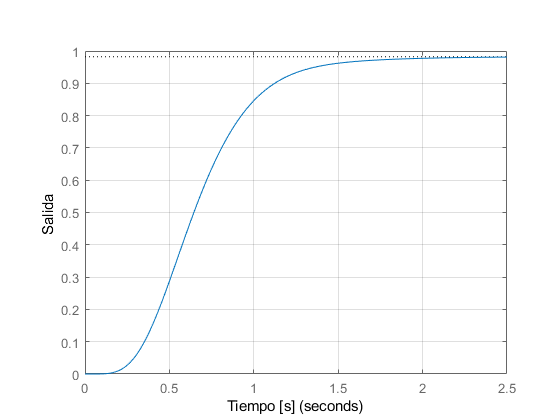


% Planta ideal de 6 polos
tf_6polos_ideal = 1/(s*0.1 + 1)^6;

% Planta de 6 polos modelada con la prbs
tf_6polos_prbs_medida = tf([5.671618964260604e+05] , [1,58.284099674190490,1.284445491209403e+03,1.622971004687713e+04,1.087898782652298e+05,3.983829952470905e+05,5.775054615523315e+05]);
tf_6polos_num = [5.671618964260604e+05];
tf_polos_den = [1,58.284099674190490,1.284445491209403e+03,1.622971004687713e+04,1.087898782652298e+05,3.983829952470905e+05,5.775054615523315e+05];


% Planta de orden 1 modelada con la prbs, retardo real
G_sin_retardo = (K_p)/(1+s*T);
G_fopdt = G_sin_retardo; 
G_fopdt.InputDelay = L; 

% Planta de orden 1 con pade
G_fopdt_pade = G_sin_retardo * (1 - (L/2)*s) / (1 + (L/2)*s);

%% Respuesta a lazo abierto – Planta 6 polos (PRBS)

figure
step(tf_6polos_prbs_medida)
grid on
title(' ')
xlabel('Tiempo [s]')
ylabel('Salida')


% Obtener métricas de velocidad de respuesta
info_6polos = stepinfo(tf_6polos_prbs_medida);

% Mostrar resultados en consola
disp('--- Métricas de respuesta a lazo abierto ---')

--- Métricas de respuesta a lazo abierto ---


disp(['Tiempo de subida (Tr): ', num2str(info_6polos.RiseTime), ' s'])

Tiempo de subida (Tr): 0.72986 s


disp(['Tiempo de establecimiento (Ts): ', num2str(info_6polos.SettlingTime), ' s'])

Tiempo de establecimiento (Ts): 1.5045 s


disp(['Sobreimpulso (%): ', num2str(info_6polos.Overshoot)])

Sobreimpulso (%): 0


## Transferencias LC

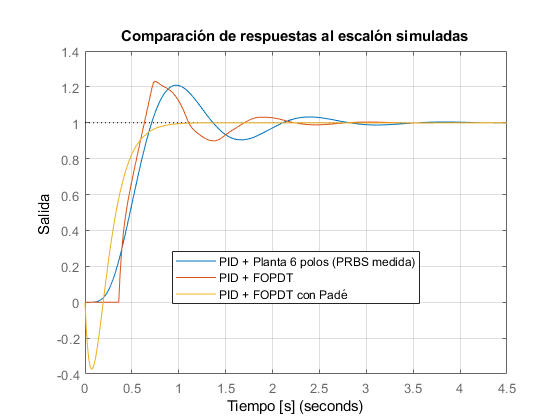



T_PID_6polos = feedback(tf_6polos_prbs_medida*PID, 1);
T_PID_fopdt = feedback(G_fopdt*PID, 1);
T_PID_pade = feedback(G_fopdt_pade*PID, 1);

% Gráfico
figure;
h = stepplot(T_PID_6polos, T_PID_fopdt, T_PID_pade);
grid on;

title('Comparación de respuestas al escalón simuladas');
xlabel('Tiempo [s]');
ylabel('Salida');

legend( ...
    'PID + Planta 6 polos (PRBS medida)', ...
    'PID + FOPDT', ...
    'PID + FOPDT con Padé', ...
    'Location','Best' ...
);

## Test distintos valores de alfa (ref)

% Defino variable de Laplace
s = tf('s');

% Parametros del modelo
T =  0.33053;
L  = 0.35938;
K_p = 0.98448

K_p = 0.9845

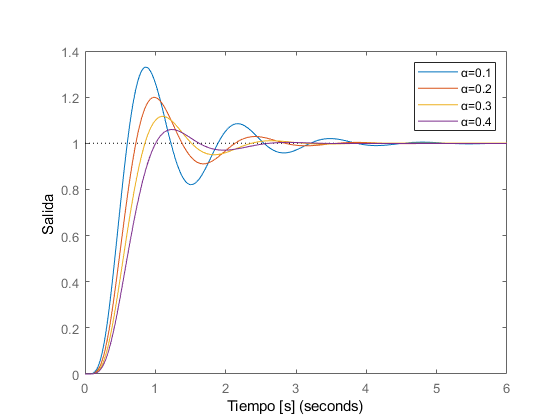


% Parametros fijos del PID
T_D = 0.5*L;
T_I = T;

%% ===== Plot 1: alfa de 0.1 a 0.4 =====
alfa_vec_1 = 0.1:0.1:0.4;

figure
hold on
grid on

for alfa = alfa_vec_1

    T_0 = (sqrt(alfa^2 + alfa) + alfa)*L/2;
    k_c = 2*T/(K_p*(L + 4*T_0));

    PID = (k_c*(1 + T_I*s)*(1 + T_D*s)) / ...
          (T_I*s*(1 + alfa*T_D*s));

    T_PID_6polos = feedback(tf_6polos_prbs_medida*PID, 1);

    step(T_PID_6polos)

end

% title('Respuesta al escalón – \alpha = 0.1 a 0.4')
title(' ')
xlabel('Tiempo [s]')
ylabel('Salida')
legend('α=0.1','α=0.2','α=0.3','α=0.4')

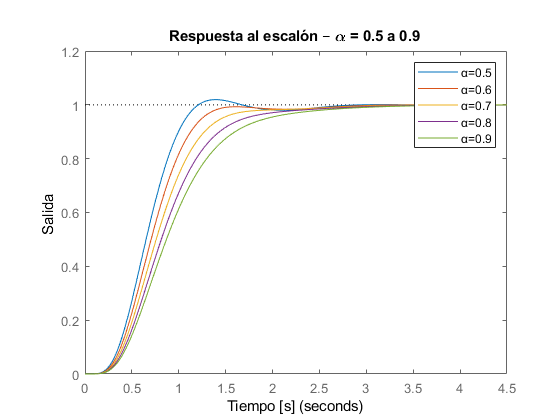



%% ===== Plot 2: alfa de 0.5 a 0.9 =====
alfa_vec_2 = 0.5:0.1:0.9;

figure
hold on
grid on

for alfa = alfa_vec_2

    T_0 = (sqrt(alfa^2 + alfa) + alfa)*L/2;
    k_c = 2*T/(K_p*(L + 4*T_0));

    PID = (k_c*(1 + T_I*s)*(1 + T_D*s)) / ...
          (T_I*s*(1 + alfa*T_D*s));

    T_PID_6polos = feedback(tf_6polos_prbs_medida*PID, 1);

    step(T_PID_6polos)

end

title('Respuesta al escalón – \alpha = 0.5 a 0.9')
xlabel('Tiempo [s]')
ylabel('Salida')
legend('α=0.5','α=0.6','α=0.7','α=0.8','α=0.9')

## Test distintos valores de alfa (per)

% Defino variable de Laplace
s = tf('s');

% Parametros del modelo
T =  0.33053;
L  = 0.35938;
K_p = 0.98448

K_p = 0.9845

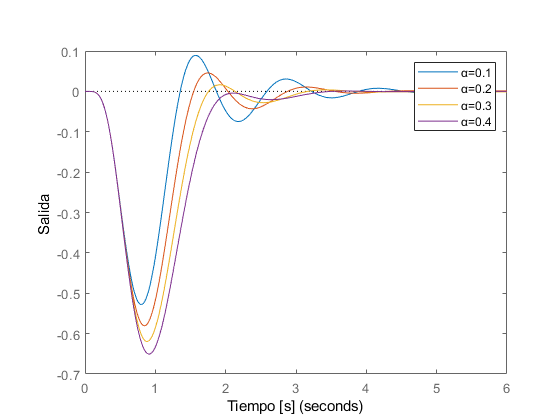


% Planta FOPDT sin retardo (para estabilidad numérica)
G = tf_6polos_prbs_medida;
% tf_6polos_prbs_medida = tf([5.671618964260604e+05] , [1,58.284099674190490,1.284445491209403e+03,1.622971004687713e+04,1.087898782652298e+05,3.983829952470905e+05,5.775054615523315e+05]);


% Parametros fijos del PID
T_D = 0.5*L;
T_I = T;

%% ===== Plot 1: rechazo a perturbación (alfa 0.1 a 0.4) =====
alfa_vec_1 = 0.1:0.1:0.4;

figure
hold on
grid on

for alfa = alfa_vec_1

    T_0 = (sqrt(alfa^2 + alfa) + alfa)*L/2;
    k_c = 2*T/(K_p*(L + 4*T_0));

    % PID (forma robusta)
    num = k_c * conv([T_I 1], [T_D 1]);
    den = conv([T_I 0], [alfa*T_D 1]);
    PID = tf(num, den);

    % Transferencia perturbacion → salida
    SG = G / (1 + G*PID);

    % Escalón de perturbación -1 V
    step(-1 * SG)

end
% title('Rechazo a perturbaciones – \alpha = 0.1 a 0.4')
title(' ')
xlabel('Tiempo [s]')
ylabel('Salida')
legend('α=0.1','α=0.2','α=0.3','α=0.4')

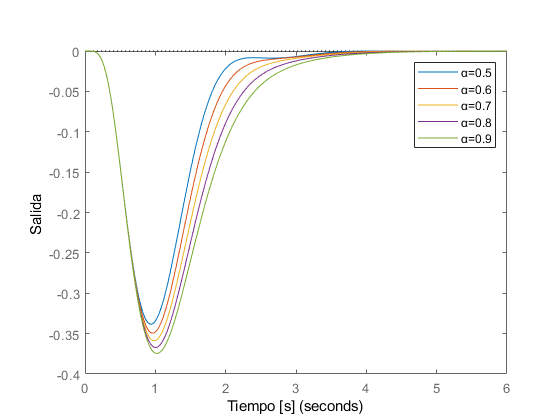



%% ===== Plot 2: rechazo a perturbación (alfa 0.5 a 0.9) =====
alfa_vec_2 = 0.5:0.1:0.9;

figure
hold on
grid on

for alfa = alfa_vec_2

    T_0 = (sqrt(alfa^2 + alfa) + alfa)*L/2;
    k_c = 2*T/(K_p*(L + 4*T_0));

    num = k_c * conv([T_I 1], [T_D 1]);
    den = conv([T_I 0], [alfa*T_D 1]);
    PID = tf(num, den);

    SG = G / (1 + G*PID);

    step(-0.5 * SG)

end
%title('Rechazo a perturbaciones – \alpha = 0.5 a 0.9')
title(' ')
xlabel('Tiempo [s]')
ylabel('Salida')
legend('α=0.5','α=0.6','α=0.7','α=0.8','α=0.9')

## Transferencias perturbación en la accion de control

SG_6polos = tf_6polos_prbs_medida/(1+tf_6polos_prbs_medida*PID);
SG_fopdt  = G_fopdt/(1+G_fopdt*PID);
SG_fopdt.InputDelay = L; 
SG_pade   = G_fopdt_pade/(1+G_fopdt_pade*PID);

## Discretizacion de la planta, cálculo de los coeficientes

Como es un controlador de 2 ceros y 2 polos:


$$\frac{U\left(z\right)}{E\left(z\right)}=\frac{a_0 +a_1 z^{-1} +a_2 z^{-2} }{{1-\;b}_1 z^{-1} -b_2 z^{-2} }$$


La ecuación en diferencias tiene que tener la siguiente forma:


$$u\left\lbrack k\right\rbrack =a_0 e\left\lbrack k\right\rbrack +a_1 e\left\lbrack k-1\right\rbrack +a_2 e\left\lbrack k-2\right\rbrack +b_1 u\left\lbrack k-1\right\rbrack +b_2 e\left\lbrack k-2\right\rbrack$$


% Defino parametros del modelo
s = tf('s');

T =  0.33053;
L  = 0.35938;
K_p = 0.98448;
Tm = 0.030;

% Defino parametros del PID

T_D = 0.5*L;
T_I = T;
alfa = 0.2;
T_0 = (sqrt(alfa*alfa + alfa) + alfa)*L/2;
k_c  = 2*T/(K_p*(L  + 4*T_0));

PID = (k_c*(1+T_I*s)*(1+T_D*s))/(T_I*s*(1+alfa*T_D*s));

PIDz = c2d(PID, Tm, 'zoh');
[x, y] = tfdata(PIDz, 'v'); % Coef multiplicados por 1000:
coeficientes_a0_a1_a2 = x*1000

coeficientes_a0_a1_a2 = 	1.0e+03 *

    3.9256   -7.1423    3.2570


coeficientes_b0_b1_b2 = -y*1000

coeficientes_b0_b1_b2 = 	1.0e+03 *

   -1.0000    1.4340   -0.4340


## Robustez para la familia de modelos

El modelo de incertidumbre utilizado fue el incerteza multiplicativa.

Se debe cumplir 3

La variable t (tau) puede variar entre 0.08 y 0.12 (variacion de 20% del 0.1 nominal)

t1 = ureal('t1', 0.1, 'Range', [0.08 0.12]);
t2 = ureal('t2', 0.1, 'Range', [0.08 0.12]);
t3 = ureal('t3', 0.1, 'Range', [0.08 0.12]);
t4 = ureal('t4', 0.1, 'Range', [0.08 0.12]);
t5 = ureal('t5', 0.1, 'Range', [0.08 0.12]);
t6 = ureal('t6', 0.1, 'Range', [0.08 0.12]);


Definimos la familia de plantas

s = tf('s');
G = 1 / ((s*t1+1)*(s*t2+1)*(s*t3+1)*(s*t4+1)*(s*t5+1)*(s*t6+1))

G =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 13 states.
  The model uncertainty consists of the following blocks:
    t1: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences
    t2: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences
    t3: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences
    t4: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences
    t5: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences
    t6: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences

Type "G.NominalValue" to see the nominal value, "get(G)" to see all properties, and "G.Uncertainty" to interact with the uncertain elements.



## *Para modelo 6 polos ideal*

(WW)$|W\left(s\right)|>|\frac{G}{\textrm{Gn}}-1|\;$ (ww)


ww = G/tf_6polos_ideal -1;
WW = 1.6*s/(s + 10);

figure
bode(ww, WW)

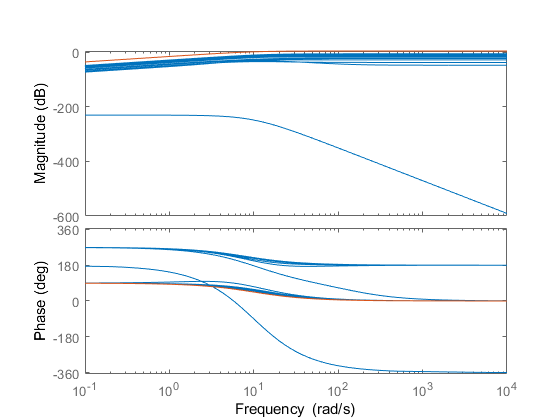

title(' ')

Verificación $|T\left(s\right)\omega \left(s\right)|<1$ modelo 6 polos

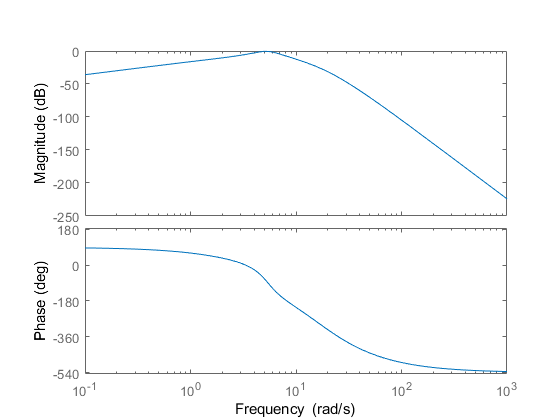

Tposta = feedback(tf_6polos_ideal*PID, 1);
robustes = Tposta*WW;

figure
bode(robustes)
title(' ')

## COMPARACIÓN

% Importar datos de simulink
out = sim('simulacionPIDv2')

out =   Simulink.SimulationOutput:

               per_simu: [1x1 timeseries] 
               ref_simu: [1x1 timeseries] 
                   tout: [1501x1 double] 
                 u_simu: [1x1 timeseries] 
               uu_simu1: [1x1 timeseries] 
                 y_simu: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


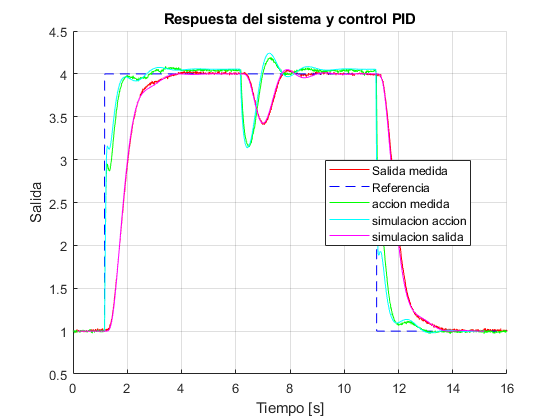

y_simu = out.y_simu;
u_simu = out.uu_simu1;

tiemp = y_simu.time - 1;
ys = y_simu.Data + 1;
us = u_simu.Data + 1;

% cambio de referencia
datos_respuesta_cambio_referencia = readtable('pidtodo.CSV');

referencia = datos_respuesta_cambio_referencia.Var1;
for i=1:20000
    if referencia(i)<1500
        referencia(i) = 1;
    else
        referencia(i) = 4;
    end
end
for i=20001:size(referencia)
    if referencia(i)<3500
        referencia(i) = 1;
    else
        referencia(i) = 4;
    end
end

datos = datos_respuesta_cambio_referencia.Var2;
datos = (datos -mean(datos(1:1000))) / 1024;
% --- Filtro pasabajos ---
fs = 2000;
fc = 50;
[b_med, a_med] = butter(4, fc/(fs/2));

datos = filter(b_med, a_med, datos)+1;

accion = datos_respuesta_cambio_referencia.Var1;
accion = (accion -mean(accion(1:1000))) / 1024;
% --- Filtro pasabajos ---
fs = 2000;
fc = 50;
[b_med, a_med] = butter(4, fc/(fs/2));

accion = filter(b_med, a_med, accion)+1;


tiempo = (0:0.0005:0.0005*(size(datos)-1));

figure; grid on; hold on;

plot(tiempo, datos, 'r');
plot(tiempo, referencia, 'b--');
plot(tiempo, accion, 'g')

plot(tiemp + tiempo(2330), us, 'c');
plot(tiemp + tiempo(2330), ys,  'm');

xlabel('Tiempo [s]');
ylabel('Salida');
title('Respuesta del sistema y control PID');

legend( ...
    'Salida medida', ...
    'Referencia', ...
    'accion medida', ...
    'simulacion accion', ...
    'simulacion salida', ...
    'Location','best');

hold off;

Comparación PID vs MPC


%Importo datos MPC
datos_mpc = readtable('mpcfinal.CSV');
accion_mpc = datos_mpc.Var2;
salida_mpc = datos_mpc.Var1;
salida_mpc = (datos_mpc.Var1 - mean(salida_mpc(1:1000))) / 1024;

% --- Filtro pasabajos salida MPC ---

fs = 2000;
fc = 50;
[b_med, a_med] = butter(4, fc/(fs/2));

salida_mpc = filter(b_med, a_med, salida_mpc)+1;

% Importar datos de simulink
out = sim('simulacionPIDv2')

out =   Simulink.SimulationOutput:

               per_simu: [1x1 timeseries] 
               ref_simu: [1x1 timeseries] 
                   tout: [1501x1 double] 
                 u_simu: [1x1 timeseries] 
               uu_simu1: [1x1 timeseries] 
                 y_simu: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


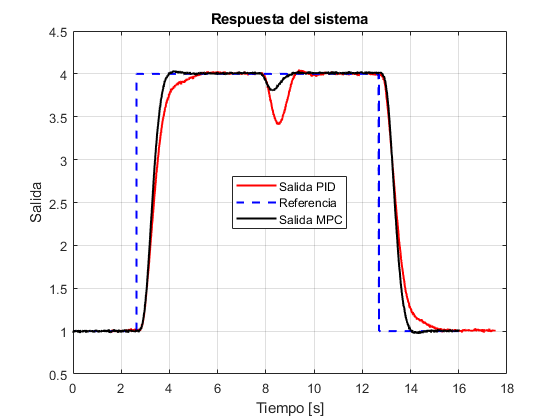

y_simu = out.y_simu;
u_simu = out.uu_simu1;

tiemp = y_simu.time - 1;
ys = y_simu.Data + 1;
us = u_simu.Data + 1;

% cambio de referencia
datos_respuesta_cambio_referencia = readtable('pidtodo.CSV');

referencia = datos_mpc.Var2;
for i=1:20000
    if referencia(i)<1500
        referencia(i) = 1;
    else
        referencia(i) = 4;
    end
end
for i=20001:size(referencia)
    if referencia(i)<3500
        referencia(i) = 1;
    else
        referencia(i) = 4;
    end
end

datos = datos_respuesta_cambio_referencia.Var2;
datos = (datos -mean(datos(1:1000))) / 1024;
% --- Filtro pasabajos ---
fs = 2000;
fc = 50;
[b_med, a_med] = butter(4, fc/(fs/2));

datos = filter(b_med, a_med, datos)+1;

% accion = datos_respuesta_cambio_referencia.Var1;
% accion = (accion -mean(accion(1:1000))) / 1024;
% % --- Filtro pasabajos ---
% fs = 2000;
% fc = 50;
% [b_med, a_med] = butter(4, fc/(fs/2));
% 
% accion = filter(b_med, a_med, accion)+1;

% Vector de tiempo (asegura longitud correcta)
Ts = 0.0005;
N  = length(datos);
tiempo = (0:N-1)*Ts;

figure;
hold on; grid on; box on;

plot(tiempo - tiempo(2312) + 2.648, datos,        'r',  'LineWidth',1.5);
plot(tiempo, referencia,   'b--','LineWidth',1.5);
plot(tiempo, salida_mpc,   'k',  'LineWidth',1.5);


xlabel('Tiempo [s]');
ylabel('Salida');
title('Respuesta del sistema');

legend( ...
    'Salida PID', ...
    'Referencia', ...
    'Salida MPC', ...
    'Location','best');

hold off;